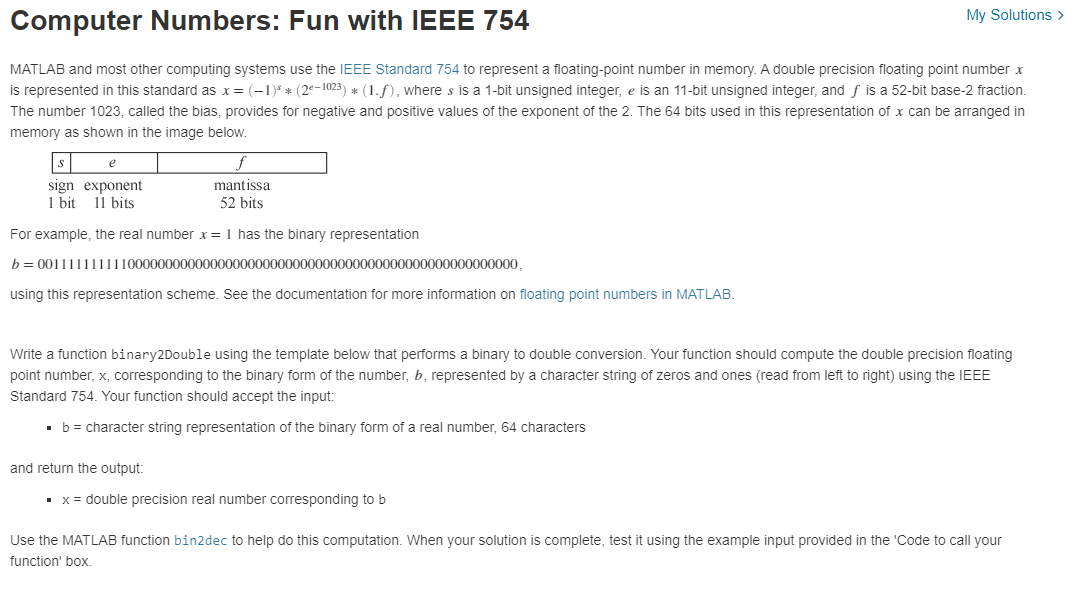

b = '0011111111110000000000000000000000000000000000000000000000000000';
b2 = '0100000001010101010010000000000000000000000000000000000000000000';
x = binary2Double(b)

x =      1


x = binary2Double(b2)

x =   85.125000000000000


function x = binary2Double(b)

% Extract the sign, exponent, and mantissa bits from the string.
    sign = b(1);
    exponent = b(2:12);
    mantissa = b(13:64);

    % Convert the bits to decimal values.
    s = bin2dec(sign);
    e = bin2dec(exponent);
    v = mantissa == '1';
    m= sum(v.*2.^(-1:-1:-52));
    
    % Convert to a real number using the IEEE Standard 754.
    x = ((-1)^s)*(2^(e-1023))*(1+m);
end
